# Find Nearest Neighbors

Find the patients in the `hospital` data set that most closely resemble the patients in `Y`, according to age and weight.

Load the `hospital` data set.

load hospital;
X = [hospital.Age hospital.Weight];

Visualise the data points on a scatter plot

figure(1)
scatter(X(:,1),X(:,2), ...
    'MarkerEdgeColor',[0 .5 .5], ...
    'MarkerFaceColor',[0 .7 .7], ...
    'LineWidth',1.5)
title('Hospital Patients: Age vs Weight')
xlabel('Age')
ylabel('Weight')
hold on

Introduce new patients

Y = [20 162; 30 169; 40 168; 50 170; 60 171];   % New patients
scatter(Y(:,1), Y(:,2), ...
    'MarkerEdgeColor',[1 .5 .5], ...
    'MarkerFaceColor',[1 0 0], ...
    'LineWidth',1.5)

Perform a `knnsearch` between `X` and `Y` to find indices of nearest neighbors.

Idx = knnsearch(X,Y);

Find the patients in `X` closest in age and weight to those in `Y`.

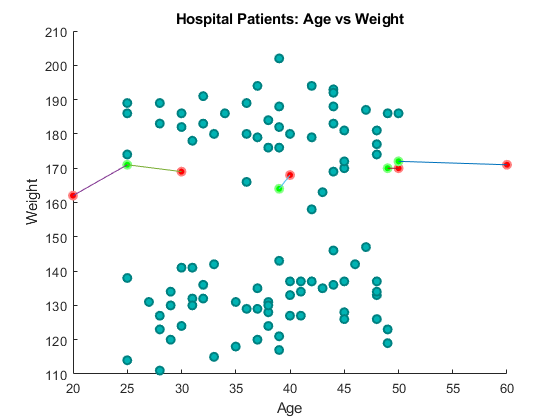

nn = X(Idx,:);
scatter(nn(:,1), nn(:,2), ...
    'MarkerEdgeColor',[.5 1 .5], ...
    'MarkerFaceColor',[0 1 0], ...
    'LineWidth',1.5)
for n = 1 : length(Y)
    plot([Y(n,1) nn(n,1)], [Y(n,2) nn(n,2)])
end

*Copyright 2012 The MathWorks, Inc.*